# **Signal and System CA2**

### **Part 1.**

1) Read and load the picture in a 3d-matrix.

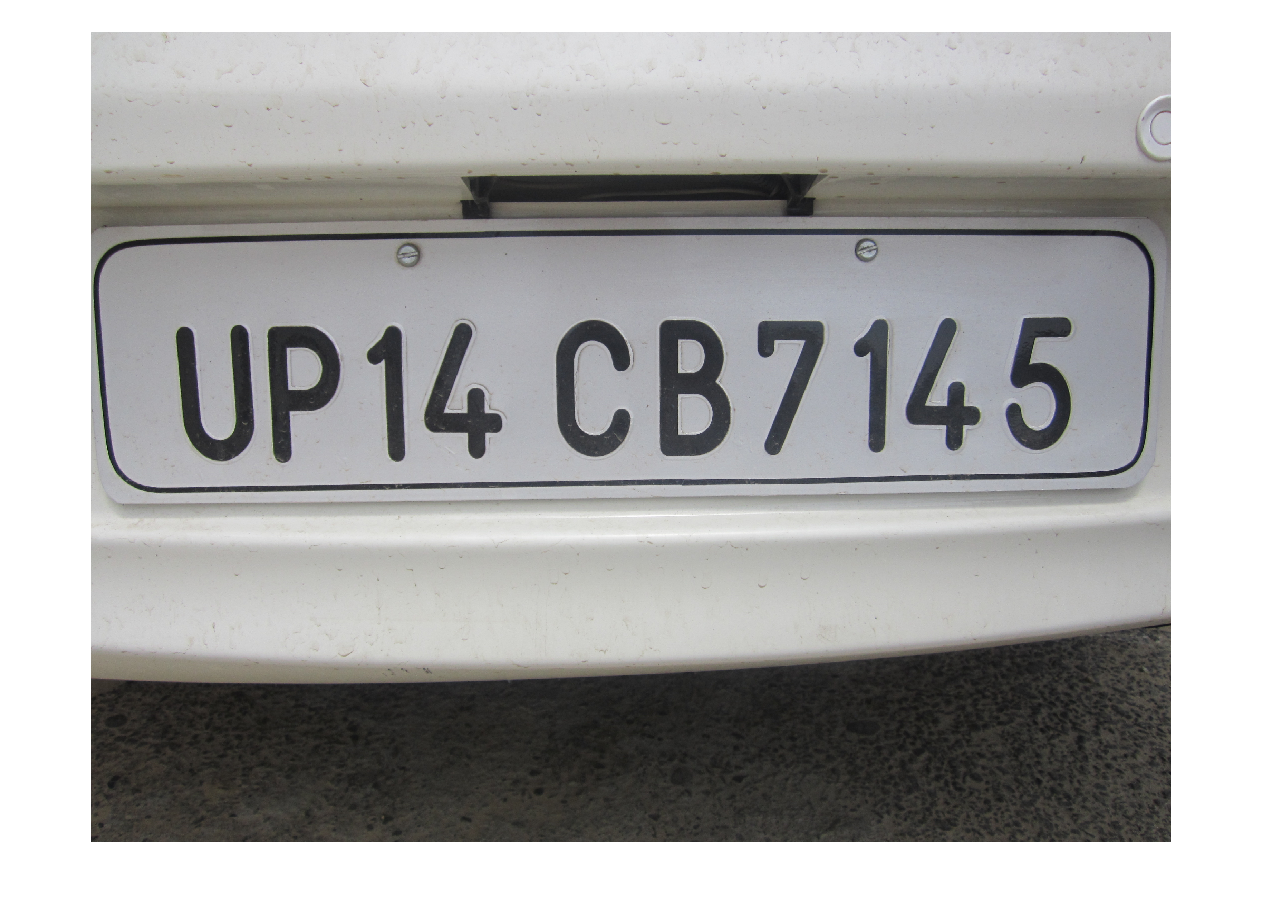

[file, path] = uigetfile({'*.jpg;*.bmp;*.png;*.tif'}, 'Select the image to process.');
source = [path, file];
picture = imread(source);
figure;
imshow(picture);

2) Resize the picture for better recognation and process.

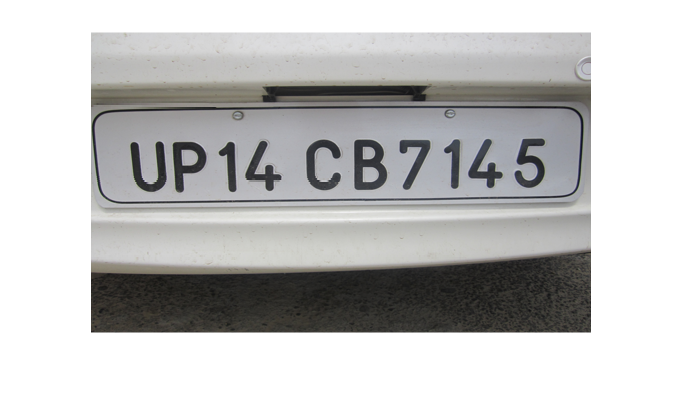

picture = imresize(picture,[300 500]);
figure;
imshow(picture);

3) Convert the picture to gray scale using `myGreyFunc. `

- We are using the below formula for gray channel:

- 
$$Gray_{channel} =  0.299 \times  Red_{channel} + 0.578 \times  Green_{channel} + 0.114 \times  Blue_{channel}$$


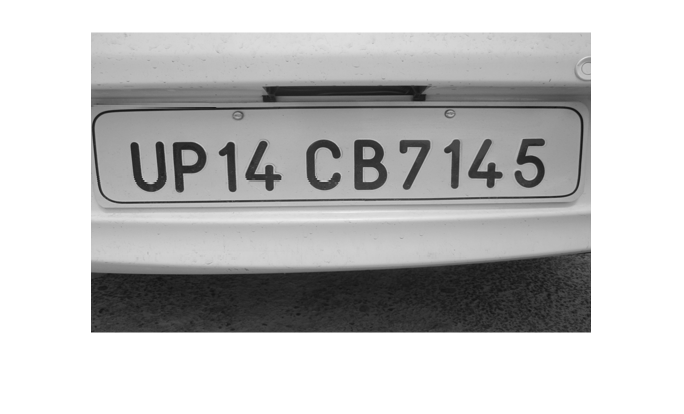

picture = myGrayFunc(picture);
figure;
imshow(picture);

4) Convert the gray picture to a binary picture using `myBinaryFunc.`

- The threshold is a number between 0 and 1. The number we assigned to threshold is close to the average of thresholds the `graythresh` function calculated for some samples.

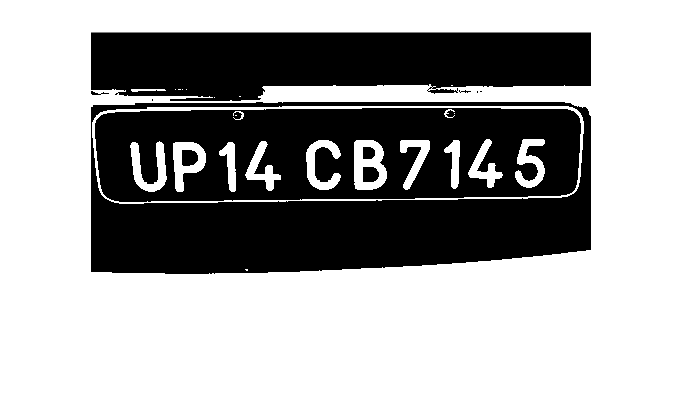

threshold = 0.4555;
picture = ~myBinaryFunc(picture, threshold);
figure;
imshow(picture);

5) Now we should remove the noisy componants in the picture using `myRemoveComFunc`.

- `myRemoveComFunc `works by looping over every pixel in the binary image. If a pixel is part of an object and has not been visited yet (using `visited` variable), it initializes a queue with this pixel and starts a BFS. The BFS checks each pixel in the connected component visited and adds it to an auxiliary binary image (`component`). Once all pixels in a component have been visited, if the size of this component is greater than or equal to `n`, which is the limit for noise, it is added to the output image. All other components which sizes are less than `P `are considered as noise and are ignored from the output.

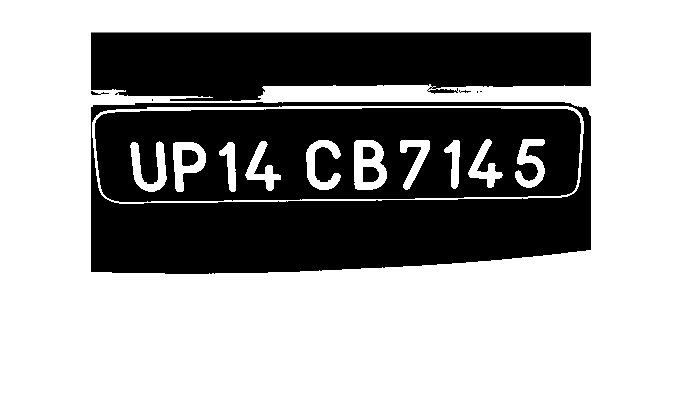

minPixelComp = 380;
picture = myRemoveComFunc(picture, minPixelComp); 
figure;
imshow(picture);

- After removing noises, we also should remove the plate's frame and other big componants which are not usefull for the segmenting of plate characters. We name set of these parts as `background` and in order to remove it, we first make a picture with only big objects (for example bigger than 2500 px).

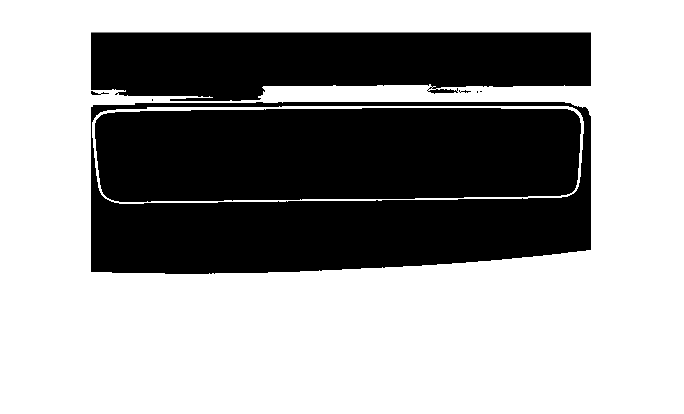

minPixelBackground = 2500;
background = myRemoveComFunc(picture, minPixelBackground);
figure;
imshow(background);

- Then with subtracting the background from the original picutre, only the needed characters and numebrs remain.

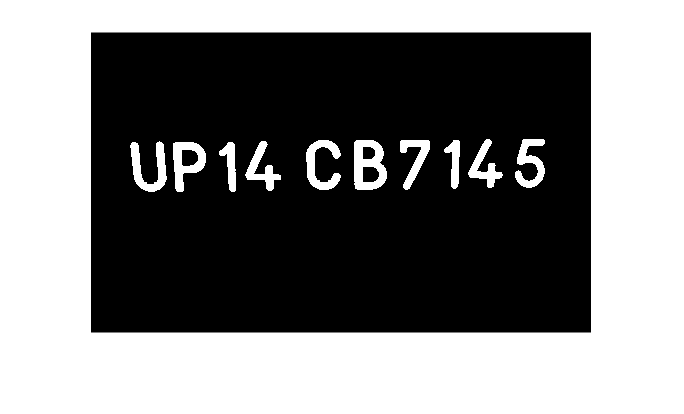

picture = picture - background;
figure;
imshow(picture);

6) In this part we need to label the components of the picture. `mySegmentationFunc` uses the exacty same BFS algorithm as the `myRemoveFunc` to detect the components. But instead of numbering them as only "1", it gives its elements in matrix a number(or a label). 

- Then we draw rectangles to show the components better and be sure of its output.

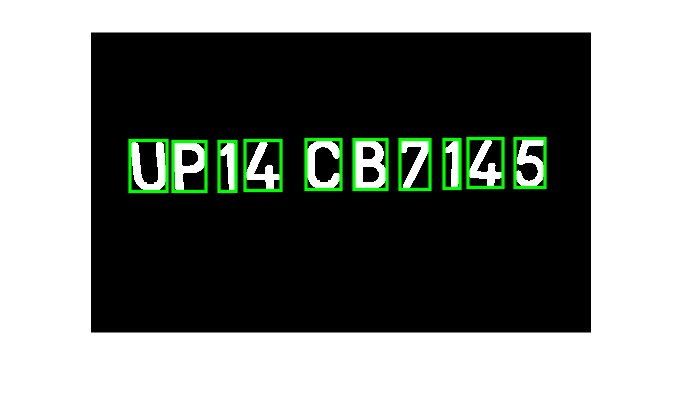

[labeledComponents, numOfComps] = mySegmentationFunc(picture);
propied = regionprops(labeledComponents, 'BoundingBox');
figure;
imshow(picture);
hold on
for n = 1 : size(propied, 1)
    rectangle('Position', propied(n).BoundingBox,'EdgeColor','g','LineWidth',2)
end
hold off

7) Now we should make decision and check each character.

- First we should read the data set from files and save its contents. At last the given dataset is mapped to the name of it in 2D-matrix of `characters`.

DATASET_FOLDER = 'English Map Set';
contents = {dir(DATASET_FOLDER).name};
files = contents(3:end);
characters = cell(2, length(files));

for i = 1:length(files)
    c2m = cell2mat(files(i));
    characters(1, i) = {imread([DATASET_FOLDER, '\', c2m])};
    characters(2, i) = {c2m(1:find(c2m == '.') - 1)};
end
save("EnglishCharacters.mat", 'characters');

- Now we check each previously labeled component with the dataset and caluclate the 2D-corrolation between them using `corr2` to find the best match for the component. For better results, only if the maximum calculated corrolation is bigger than a limit, it is considered as an answer.

final_output=[];
t = [];
for n = 1 : numOfComps
    [r, c] = find(labeledComponents==n);
    Y = picture(min(r):max(r), min(c):max(c));
    Y = imresize(Y, [42,24]);
    
    ro = zeros(1,size(characters, 2));
    for k = 1 : size(characters, 2)   
        ro(k) = corr2(characters{1,k},Y);
    end
    
    [MAXRO, pos] = max(ro);
    if MAXRO > .5
        out = cell2mat(characters(2, pos));       
        final_output = [final_output out];
    end
end

8) In the end we print the output and also write it to file.

file = fopen('english_plate.txt', 'wt');
fprintf(file,'%s\n',final_output);
fclose(file);
final_output

final_output = 'UP14CB7145'

All implemented functions for this part:

function grayPicture = myGrayFunc(picture)
    redChannel = picture(:, :, 1);
    greenChannel = picture(:, :, 2);
    blueChannel = picture(:, :, 3);
    
    grayPicture = 0.299 * double(redChannel) + 0.578 * double(greenChannel) + 0.114 * double(blueChannel);
    grayPicture = uint8(grayPicture);
end

function binaryPicture = myBinaryFunc(picture, threshold)
    if size(picture, 3) == 3
        picture = myGrayFunc(picture);
    end

    binaryPicture = im2double(picture) > threshold;
end

function outputPicture = myRemoveComFunc(picture, n)
    [rows, cols] = size(picture);
    
    outputPicture = false(size(picture));
    visited = false(size(picture));
    
    neighbors = [-1 -1; -1 0; -1 1; 0 -1; 0 1; 1 -1; 1 0; 1 1];
    for i = 1:rows
        for j = 1:cols
            if picture(i, j) && ~visited(i, j)
                component = false(size(picture));
                queue = [i j];
                
                while ~isempty(queue)
                    pixel = queue(1, :);
                    queue(1, :) = [];
                    
                    if ~visited(pixel(1), pixel(2))
                        visited(pixel(1), pixel(2)) = true;
                        component(pixel(1), pixel(2)) = true;
                        
                        for k = 1:size(neighbors, 1)
                            neighbor = pixel + neighbors(k, :);
                            if neighbor(1) >= 1 && neighbor(1) <= rows && neighbor(2) >= 1 &&...
                                    neighbor(2) <= cols && picture(neighbor(1), neighbor(2)) && ...
                                    ~visited(neighbor(1), neighbor(2))
                                queue(end + 1, :) = neighbor;
                            end
                        end
                    end
                end
                if nnz(component(:)) >= n
                    outputPicture = outputPicture | component;
                end
            end
        end
    end
end


function [labeledComponents, numOfObjects] = mySegmentationFunc(picture)
    [rows, cols] = size(picture);
    visited = false(size(picture));
    labeledComponents = zeros(size(picture));
    numOfObjects = 0;
    
    neighbors = [-1 -1; -1 0; -1 1; 0 -1; 0 1; 1 -1; 1 0; 1 1];
    for j = 1:cols
        for i = 1:rows
            if picture(i, j) && ~visited(i, j)
                numOfObjects = numOfObjects + 1;
                queue = [i j];
                
                while ~isempty(queue)
                    pixel = queue(1, :);
                    queue(1, :) = [];
                    if ~visited(pixel(1), pixel(2))
                        visited(pixel(1), pixel(2)) = true;
                        labeledComponents(pixel(1), pixel(2)) = numOfObjects;
                        
                        for k = 1:size(neighbors, 1)
                            neighbor = pixel + neighbors(k, :);
                            if neighbor(1) >= 1 && neighbor(1) <= rows && neighbor(2) >= 1 && ...
                                    neighbor(2) <= cols && picture(neighbor(1), neighbor(2)) && ...
                                    ~visited(neighbor(1), neighbor(2))
                                queue(end + 1, :) = neighbor;
                            end
                        end
                    end
                end
            end
        end
    end
end
